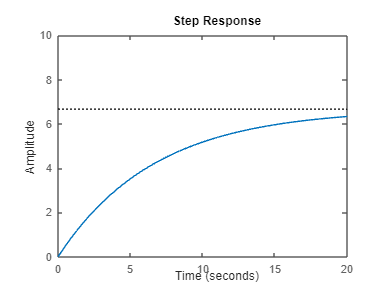

clc;
close all;
clear ;
%transfer function
Kp = 1;
Ki = 1;
Kd = 1;
s = tf('s');
c = Kp + Ki/s + Kd*s;
%step response with pi-controller 
m = 1000;
b = 50;
r = 10;
s = tf('s');
P_cruise = 1/(m*s + b);

Kp = 100;
C = pid(Kp);
T = feedback(C*P_cruise,1);
t = 0:0.1:20;
figure(1);
step(r*T,t)
axis([0 20 0 10])

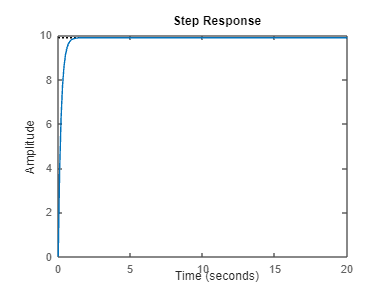


Kp = 5000;
C = pid(Kp);
T = feedback(C*P_cruise,1);
figure(2);
step(r*T,t);
axis([0 20 0 10]);

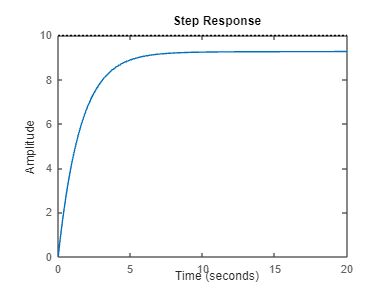


Kp = 600;
Ki = 1;
C = pid(Kp,Ki);
T = feedback(C*P_cruise,1);
figure(3);
step(r*T,t);
axis([0 20 0 10]);

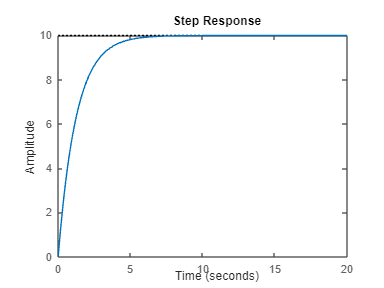


Kp = 800;
Ki = 40;
C = pid(Kp,Ki);
T = feedback(C*P_cruise,1);
figure(4);
step(r*T,t)
axis([0 20 0 10])